clc;clear;close all;

## 读取点

warning off
[num,txt,raw] = xlsread("测试excel2.xlsx");
num(4:5,:)=[];
x = num(8,~isnan(num(8,:)));
y = num(9,~isnan(num(9,:)));
z = num(7,~isnan(num(7,:)));
azimuth = num(4,1);
elevation = num(4,2);
Points = [x;y;z];

PAB = Points(:,5);
% P1 = num(1,[3,4,2]);
% P2 = num(2,[3,4,2]);


P1 = [-0.2517,0.48297,0.512];
P2 = [-0.25,-0.3546,-0.4];

## 复测数据

% xx = num(13,~isnan(num(13,:)));
% yy = num(14,~isnan(num(14,:))); 
% zz = num(12,~isnan(num(12,:)));
% PointFC = [xx;yy;zz];
% scatter3(xx,yy,zz,50,'filled','yellow')

## 拟合圆柱

[Mcenter,MTaon,Mradial,Err_every,Bottom_round_center1,Bottom_round_center2]=Calculate_accurate_cylinders_from_multiple_measurement_points2(Points,P1,P2);

## A、B面点测试

numShengLu = 4;
phi = deg2rad(65);

toff = zeros(1,2*numShengLu);
roff = zeros(1,2*numShengLu);

Ang = ShengLuJiaoJiSuan(numShengLu)

Ang =     0.9425    0.3142   -0.3142   -0.9425   -0.9425   -0.3142    0.3142    0.9425



[PointTable_A_off,PointTable_B_off] = Calculat_A_and_B_Points_after_Offest2(MTaon',Mcenter',Mradial,PAB,phi,Ang,toff,roff)

E xyz: 0.903756, 0.294748, 0.310401
AngOring: 0.008775
A1 xyz: 0.836579, -0.130954, 0.390050


PointTable_A_off =     0.8366    0.5386    0.1678   -0.1342   -0.1407    0.1573    0.5281    0.8301
   -0.1310   -0.3626   -0.3659   -0.1395    0.6018    0.8334    0.8367    0.6103
    0.3900    0.4633    0.4633    0.3900    0.1530    0.0797    0.0797    0.1530


PointTable_B_off =     0.8346    0.5354    0.1646   -0.1361   -0.1387    0.1604    0.5312    0.8320
    0.0922   -0.0015   -0.0048    0.0837    0.3786    0.4723    0.4755    0.3871
    0.6316    0.8542    0.8542    0.6316   -0.0886   -0.3112   -0.3112   -0.0886


## 复测函数

% [Distance,theta,LTPY,TiC,Wquanzhong1,Wquanzhong2]=YuanXingFuCe(PointFC,numShengLu,Mcenter,MTaon,Mradial,phi)

## 绘图验证

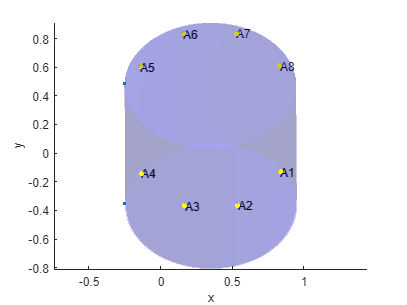

figure
hold on
% 绘制圆柱面
plotcylinder(Bottom_round_center1,Bottom_round_center2,'b',Mradial,0.2)
xlabel('x')
ylabel('y')
zlabel('z')
axis equal
camlight;
lighting flat;

% 绘制散点
% scatter3(Points(1,:),Points(2,:),Points(3,:),5,"filled");
scatter3([P1(1),P2(1)],[P1(2),P2(2)],[P1(3),P2(3)],10,"filled");

PointTable_A_off = PointTable_A_off';
PointTable_B_off = PointTable_B_off';
scatter3(PointTable_A_off(:,1),PointTable_A_off(:,2),PointTable_A_off(:,3),20,'filled','yellow')
% scatter3(PointTable_B_off(:,1),PointTable_B_off(:,2),PointTable_B_off(:,3),20,'filled','yellow')
text(PointTable_A_off(1,1),PointTable_A_off(1,2),PointTable_A_off(1,3),'A1')
text(PointTable_A_off(2,1),PointTable_A_off(2,2),PointTable_A_off(2,3),'A2')
text(PointTable_A_off(3,1),PointTable_A_off(3,2),PointTable_A_off(3,3),'A3')
text(PointTable_A_off(4,1),PointTable_A_off(4,2),PointTable_A_off(4,3),'A4')
text(PointTable_A_off(5,1),PointTable_A_off(5,2),PointTable_A_off(5,3),'A5')
text(PointTable_A_off(6,1),PointTable_A_off(6,2),PointTable_A_off(6,3),'A6')
text(PointTable_A_off(7,1),PointTable_A_off(7,2),PointTable_A_off(7,3),'A7')
text(PointTable_A_off(8,1),PointTable_A_off(8,2),PointTable_A_off(8,3),'A8')